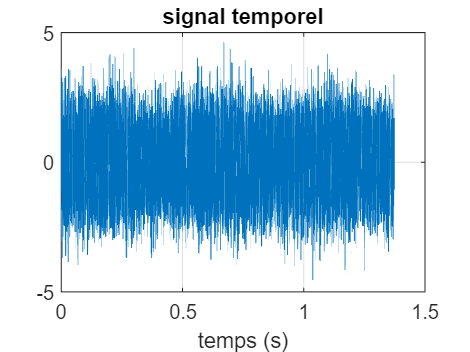

clear all;
close all;

load('seqclavier.mat');

% 1)
% Domaine temporel 
fe=32768;
Te=1/fe;
N=length(yb);
k=0:N-1;
t=k*Te;
f=k*fe/N;

figure
plot(t, yb);
title('signal temporel')
xlabel('temps (s)')
grid on 

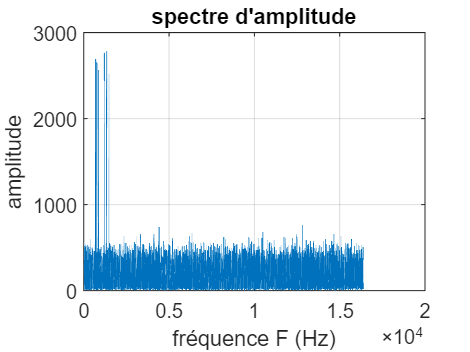


% 2)
% Zero padding
Nfft=N*4;
Yb=abs(fft(yb,Nfft));
Yb=Yb(1:Nfft/2); 
F=[0:(Nfft/2)-1]*fe/Nfft; % pour avoir uniquement le spectre en 0 et fe/2

figure
plot(F, Yb)
title('spectre d''amplitude')
xlabel('fréquence F (Hz)')
ylabel('amplitude')
grid on 

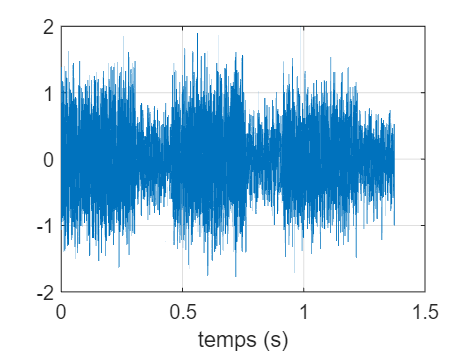


% 3)
% Filtrage
fc=2*1500/fe;
[A B]=butter(16, fc);
Ybf=filtfilt(A, B, yb);

figure
plot(t, Ybf)
xlabel('temps (s)')
grid on 

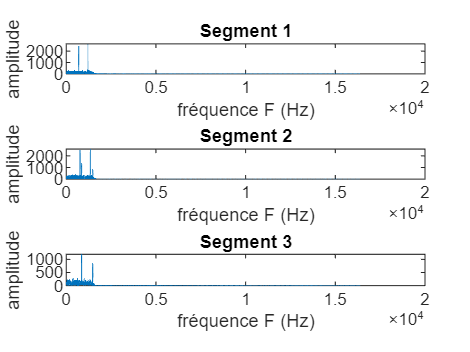


% 4)
% Segments
y1=Ybf(1:15000); Y1=abs(fft(y1, Nfft)); Y1=Y1(1:Nfft/2);
y2=Ybf(15001:35000); Y2=abs(fft(y2, Nfft)); Y2=Y2(1:Nfft/2);
y3=Ybf(35001:45000); Y3=abs(fft(y3, Nfft)); Y3=Y3(1:Nfft/2);

figure
subplot(3, 1, 1); plot(F, Y1); title('Segment 1'); xlabel('fréquence F (Hz)'); ylabel('amplitude');
subplot(3, 1, 2); plot(F, Y2); title('Segment 2'); xlabel('fréquence F (Hz)'); ylabel('amplitude');
subplot(3, 1, 3); plot(F, Y3); title('Segment 3'); xlabel('fréquence F (Hz)'); ylabel('amplitude');